# Aula 09

#### 
$$G(s) = \frac{9}{s^2 + 3Rs + 9}$$
        
$$p_{1,2} = -\frac{3R}{2} \pm \frac{3}{2}\sqrt{R^2-4}$$


R = 0.5;
% -----------------------------------------
% s do tipo tf
s = tf('s');
G = 9/(s^2+3*R*s+9);
p = pole(G)

p =   -0.7500 + 2.9047i
  -0.7500 - 2.9047i


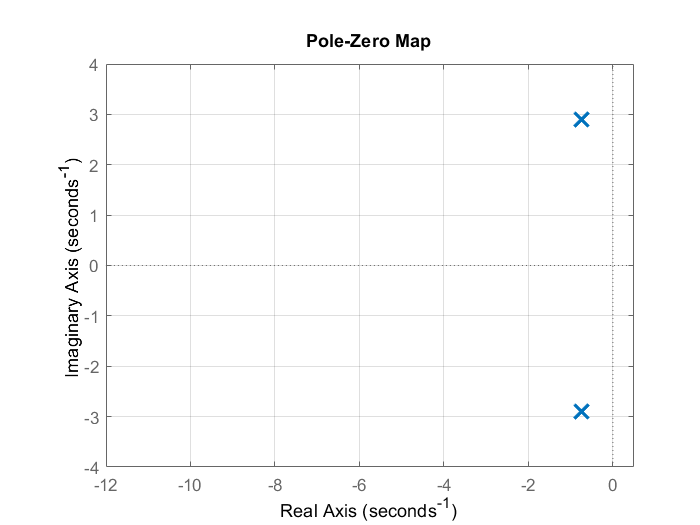


% -----------------------------------------
% Diagrama de polos e zeros
pzmap(G);

% perfumaria {
ax1 = gca;
ax1.XLim = [-12 0.5];
ax1.YLim = [-4 4];
ax1.XGrid = 'on';
ax1.YGrid = 'on';
ax1.Children(1).Children(1).MarkerSize = 12;    % altera o tamanho do simbolo x no gráfico
ax1.Children(1).Children(2).MarkerSize = 12;    % altera o tamanho do simbolo x no gráfico
ax1.Children(1).Children(1).LineWidth=2;        % altera a espessura do simbolo x no gráfico
ax1.Children(1).Children(2).LineWidth=2;        % altera a espessura do simbolo x no gráfico

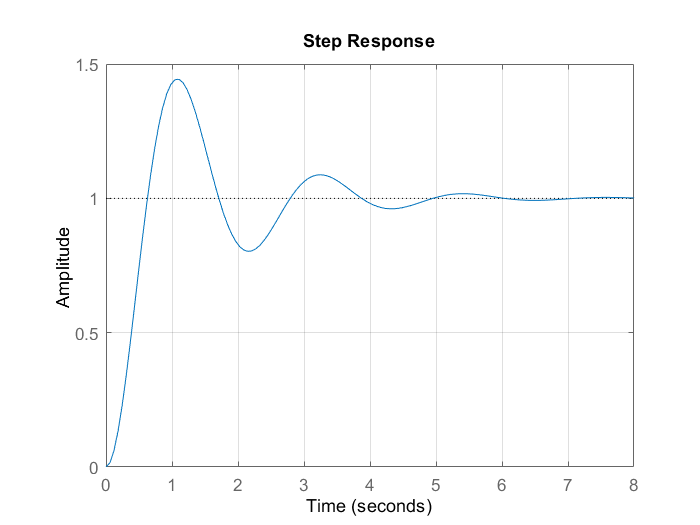

% }
% -----------------------------------------
% Resposta ao degrau unitario
step(G);

% perfumaria {
ax2 = gca;
ax2.XLim = [0 8];
grid on;

% }